# Resolvent Analysis of Plane Poisueille Flow

clc
clear

Resolvent analysis, as employed here, is a method for studying the linear amplication mechanisms in the Navier-Stokes equation by treating the nonlinear term as an external forcing to the linear system. A summary -

Consider the governing equations for incompressible flow


$$\frac{\partial \mathbf{u}}{\partial t}+\mathbf{u} \cdot \nabla \mathbf{u}=-\nabla p+\frac{1}{Re_{\tau}} \Delta \mathbf{u} $$



$$\nabla \cdot \mathbf{u}=0 $$


Let the total velocity be the sum of a mean velocity and fluctuations


$$\mathbf{u} = \mathbf{U} + \tilde \mathbf{u}$$


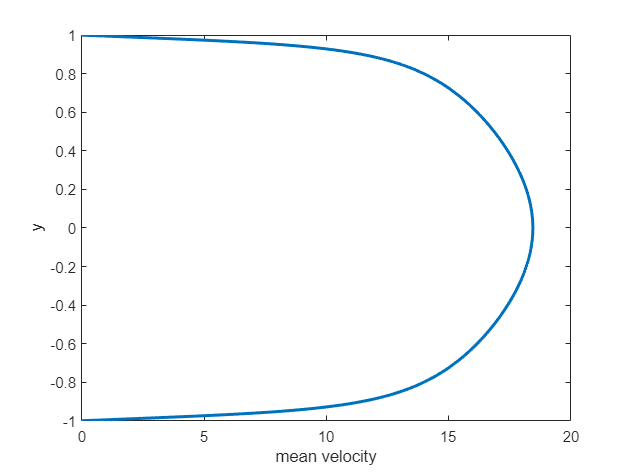

%plot the mean velocity
Re   = 200;
N    = 201;
[y, ~, ~, ~, U0] = channelMeanVel(Re, N);

plot(U0,y,'linewidth',2)
ylabel('y');
xlabel('mean velocity');

and Fourier transform the velocity field

$\left[\begin{array}{c}
\mathbf{u}(x, y, z, t) \\
p(x, y, z, t)
\end{array}\right]=\int\int\int_{-\infty}^{\infty}\left[\begin{array}{c}
\hat{\mathbf{u}}(\mathbf{k} ; y) \\
\hat{p}(\mathbf{k} ; y)
\end{array}\right] e^{i\left(k_{x} x +k_{z} z-\omega t\right)} \mathrm{d} k_{x} \mathrm{~d} k_{z} \mathrm{~d} \omega$.

Thus our governing equations now become


$$$\left[-i \omega+i k_{x} U\right] \hat{u}+\hat{v} U_{y}+i k_{x} \hat{p}-\frac{1}{R e_{\tau}} \Delta \hat{u}=\hat{f}_{u}$$$



$$$\left[-i \omega+i k_{x} U\right] \hat{v}+\hat{p}_{y}-\frac{1}{R e_{\tau}} \Delta \hat{v}=\hat{f}_{v}$
$$



$$
$\left[-i \omega+i k_{x} U\right] \hat{w}+i k_{z} \hat{p}-\frac{1}{R e_{\tau}} \Delta \hat{w}=\hat{f}_{w}$$$



$$$i k_{x} \hat{u}+\hat{v}_{y}+i k_{z} \hat{w}=0$,$$


In matrix form, these equations can be written as


$$\left[\begin{array}{l}
\mathbf{u_{k}} \\
p_{k}
\end{array}\right]=\left(\begin{array}{cc}
-\mathrm{i} \omega & \left.\left[\begin{array}{ll}
I & \\
& 0
\end{array}\right]-\left[\begin{array}{cc}
\mathcal{L}_{k} & -\nabla \\
\nabla^{\mathrm{T}} & 0
\end{array}\right]\right)^{-1}\left[\begin{array}{l}
I \\
0
\end{array}\right] f_{k}
\end{array}\right.$$


where $\mathcal{L}_k$ is the spatial linear Navier-Stokes operator. Thus we have a system of equations of the form


$$u_{k}=\mathcal{H}_{k} \; f_{k}$$


where $\mathcal{H}_k
$ is called the resolvent operator.

- It is defined for a given Fourier mode i.e. $(k_x, \; k_z, \; \omega)$ triplet

- It contains information only about the linear parts of the Navier Stokes equation

- To extract this information, we will use SVD


$$\mathcal{H}_{k}=\sum_{j=1}^{\infty} \psi_{k, j} \sigma_{k, j} \phi_{k, j}^{*}$$


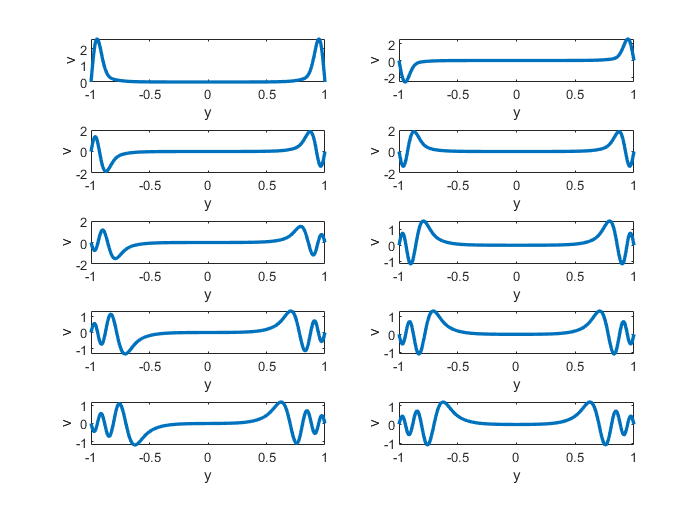

%Input parameters========================|
kx   = 1;
kz   = 6;
c    = 0.1;
omega= c*kx;
Re   = 200;
N    = 201;
Nsvd = 10; 
[y, ~, ~, ~, U0] = channelMeanVel(Re, N);
%========================================|

% get the resolvent matrix and take the SVD
[u, s, v] = getResolventSVD(kx, kz, omega, Re, N, Nsvd, U0);
[u, v] = channelSym(u, v, s, Nsvd);

% plot the results
testfield = 0;
plotResolventModes(y, u, s, v, N, Nsvd, testfield);

Note that the singular response modes peak at $y = y_c$ i.e. at the critical layer. From the expression for the resolvent


$$\mathcal{H}_{k}=\left[\begin{array}{ccc}
-\mathrm{i}\left(\omega-k_{x} U\right)-\nabla^{2} / R e_{\tau} & -\partial_{y} U & 0 \\
0 & -\mathrm{i}\left(\omega-k_{x} U\right)-\nabla^{2} / R e_{\tau} & 0 \\
0 & 0 & -\mathrm{i}\left(\omega-k_{x} U\right)-\nabla^{2} / R e_{\tau}
\end{array}\right]^{-1}$$


which can be seen to be singular for the inviscid case if $\omega = k_x U$ or $c = U$i.e. the wavespeed for the perturbation matches the local mean velocity. This prompts a peak in the response functions. The following figure shows that the location of the critial layer closely matches with the peaks of the response mode -

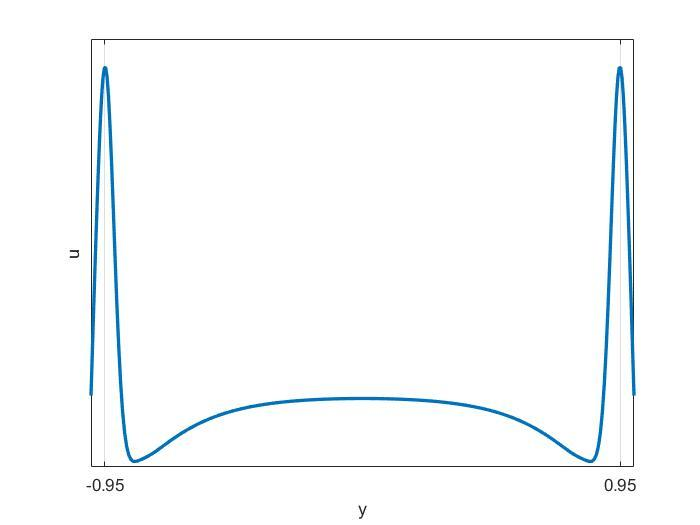

The singular values of the resolvent operator tell us which Fourier modes give large amplification of energy. To study this, let's plot the singular values as a function of the wavespeed c = ($\omega/k_x$) for a fixed $(k_x,\;k_z)$. Note that the peak occurs at $
c = U_{0max}$

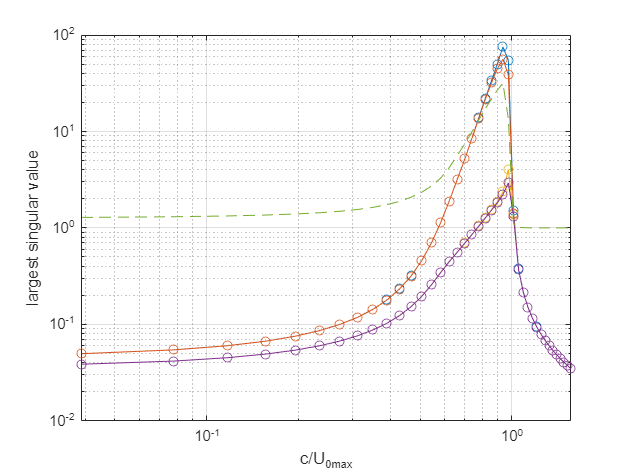

% Inputs
kx = 2; kz = 2; Re = 4000;
Nsvd = 6; N = 100;
[y, ~, ~, ~, U0] = channelMeanVel(Re, N); 
U0max = max(U0);
n = 40;
singVals = zeros(n,4); c = zeros(n,1);


for i = 1:n
    c(i) = i;
    [~, s, ~] = getResolventSVD(kx, kz, c(i)*kx, Re, N, Nsvd, U0);
    singVals(i,:) = s(1:4);
end

figure
loglog(c/U0max, singVals(:,1),'-o')
hold on
loglog(c/U0max, singVals(:,2),'-o')
loglog(c/U0max, singVals(:,3),'-o')
loglog(c/U0max, singVals(:,4),'-o')
loglog(c/U0max, singVals(:,1)./singVals(:,3),'--')
grid on
hold off
xlabel('c/U_{0max}')
ylabel('largest singular value')

This large amplification at $c = U_{0max}$ is related to critical layers in the linear NS operator.

Now let's see the effect of a resolvent response mode - creation of an element of the Uniform Momentum Zone

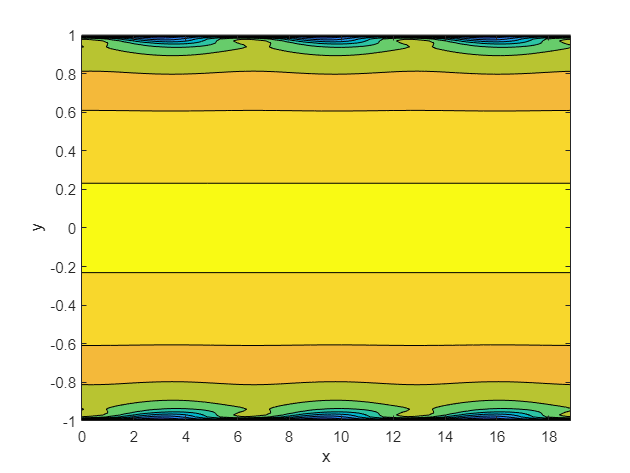


% Inputs

kx = 1; kz = 6; omega = 0.667*kx; Re = 1000;
N  = 251; Nsvd = 10; 
[y, ~, ~, ~, U0] = channelMeanVel(Re, N);
chi = 6; %(weight)

% create grid to plot the velocity field
X1 = 0:0.01:6*pi;
Y1 = -1:0.01:1;
Z1 = 0:0.1:1;
[X, Y, Z] = meshgrid(X1,Y1,Z1);

[psi, s, phi] = getResolventSVD(kx, kz, omega, Re, N, Nsvd, U0);
[psi, phi] = channelSym(psi, phi, s, Nsvd);

% Interpolate the fields to be plotted
fU0 = griddedInterpolant(flip(y),flip(U0));
umean = fU0(Y);

fpsiu = griddedInterpolant(flip(y), flip(psi(1:N,1)));
uFinal = real(chi*s(1)*fpsiu(Y).*exp(1i*kx*X + 1i*kz*Z));
uTotal = uFinal + umean;

% Plot the velocity field (in x y z)

halfy = 1:floor(length(Y1)/8);
halfx = 1:floor(length(X1)/3);

figure
data = squeeze(uTotal(:,:,1));
contourf(X1,Y1,data)
xlabel('x')
ylabel('y')

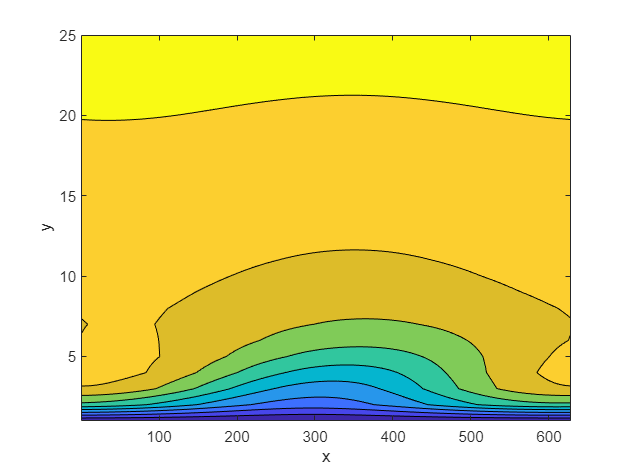


figure
data = squeeze(uTotal(halfy,halfx,1));
contourf(halfx,halfy,data)
xlabel('x')
ylabel('y')

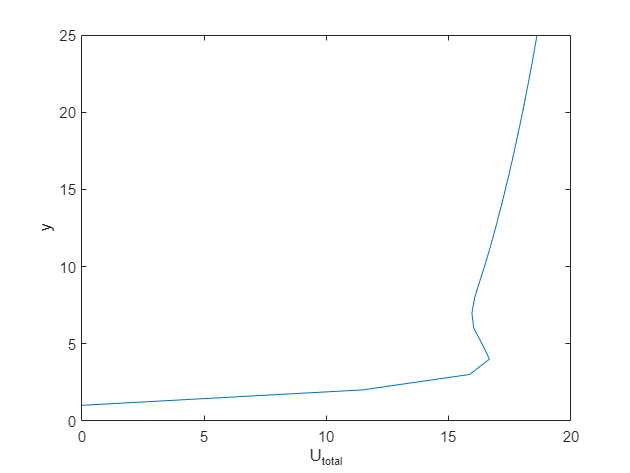


figure
data2=squeeze(uTotal(halfy,1,1));
plot(data2,halfy)
xlabel('U_{total}')
ylabel('y')

It is possible to use a few resolvent modes to construct the full UMZ (shown below). Incorporating 3 suitably determined modes can generate a highly complex field but this requires self-consistent determination of the resolvent weights - which is currently being investigated.